# Synthetic Biology - Introduction to mathematical modelling applied to biology

# Code example 2: Mathematical Modelling with Matlab

2024 © Yadira Boada, Alejandro Vignoni

## The Volterra-Lotka equations

### Differential equations with Matlab

We will use the `ode45 `command. Its structure is as follows:

%[t,X] = ode45(@(t,x) model(t,x,params),tspan,x0,options);

where

`t `is the independent variable 

`x` is the dependent variable (or vector of variables) 

`model` is the name of the function giving the differential equation, 

`params` contains parameter values 

`tspan` indicates the time over which the solution is to be obtained, 

`x0` represents the initial conditions, 

`options`  the options of the integrator algorithm.

### Volterra-Lotka 

Recall that the equations are given by this expression:


$$\frac{dx(t)}{dt}=\alpha x(t) - \beta x(t) y(t) \\
\frac{dy(t)}{dt}=\delta x(t) y(t) - \gamma y(t)$$


The Lotka-Volterra model represents the interactions of two populations, where one is the prey (denoted by x) and the other is the predator population (denoted by y).

**Main program**

First we must define the time vector: for this we discretise the time interval in order to find the numerical solutions of this equation for a particular initial condition that will be provided to us. We will discretise the interval [0,20], with a step of 0.2.

%Tiempo (seg)
tfin=8; dt=0.01;
tspan = 0:dt:tfin;

We define the parameters that in this case we are going to pass to the function. And we save them in the vector `params`. It is necessary to take into account the order in which we save the parameters in the vector `params`, it has to be the same order in which they are retrieved inside the function (at the end of the document).

% Parámetros:
a = 5;
b = 2;
d = 3;
g = 6;
params=[a,b,d,g];

and the initial conditions

% Condiciones iniciales
x0=[4 1];

% Tolerancias ode45
options=odeset('RelTol',1e-6,'Stats','off');

Finally, we solve the equation (simulate) with the ode command.

% Call ode45 Solver
[t,X] = ode23s(@(t,x) model_VL(t,x,params),tspan,x0,options);
prey = X(:,1);
pred = X(:,2);

Then, we plot the solution.

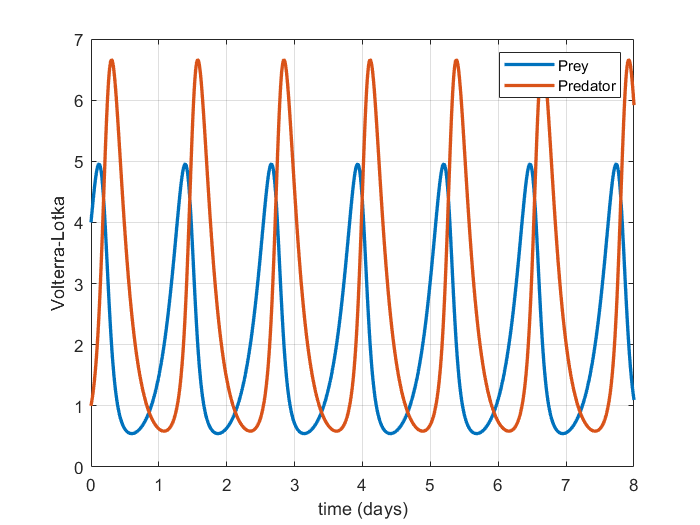

%Graph model response
figure;
plot(t,X,'LineWidth',2); grid on;
xlabel('time (days)'); ylabel('Volterra-Lotka');
legend('Prey','Predator')

Now we are going to calculate the derivatives x' and y' for different values of x and y in order to construct the velocity field in the phase portrait. To do this we determine the range for which we want to calculate the velocity field and build a grid with the meshgrid command, starting from the two vectors of x and y.

x_vector = 0:1:6;
y_vector = 0:1:6;
[xm,ym] = meshgrid(x_vector,y_vector);

We then store (preallocate) the location in memory to calculate the devivations later:

u = zeros(size(xm));
v = zeros(size(xm));

We will now use a single loop over each element to calculate the derivatives at each grid point (xm, ym):

for i = 1:numel(xm)
    Yprime = model_VL(t,[xm(i); ym(i)],params);
    u(i) = Yprime(1);
    v(i) = Yprime(2);
end

Then for each set of values of x and y, we have the values of their derivatives u, and v. 

Now we can calculate three trajectories, starting from different initial conditions to draw them on the phase portrait. We calculate and draw the trajectories in the phase plane:

figure;
plot(X(:,1),X(:,2),'LineWidth',2); grid on;
hold on
xlabel('Prey'); ylabel('Predator');
title('Phase portrait')
[t,X] = ode23(@(t,x) model_VL(t,x,params),tspan,[2 4.5],options);
prey = [prey X(:,1)];
pred = [pred X(:,2)];
plot(X(:,1),X(:,2),'LineWidth',2);

[t,X] = ode23(@(t,x) model_VL(t,x,params),tspan,[2 5.5],options);
prey = [prey X(:,1)];
pred = [pred X(:,2)];
plot(X(:,1),X(:,2),'LineWidth',2);

[t,X] = ode23(@(t,x) model_VL(t,x,params),tspan,[2 2.5],options);
prey = [prey X(:,1)];
pred = [pred X(:,2)];
plot(X(:,1),X(:,2),'LineWidth',2);


and draw the velocity field with the command `quiver`

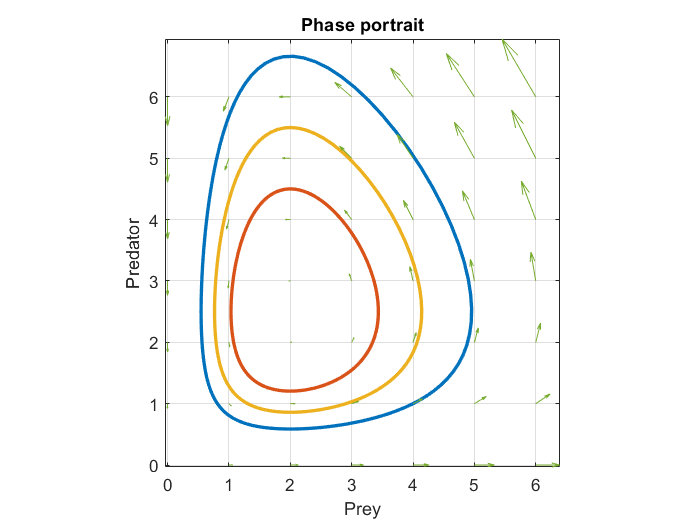

quiver(xm,ym,2*u,2*v); 
axis tight equal;

Ademas vamos a dibujars las presas y predadores para las distintas condiciones iniciales

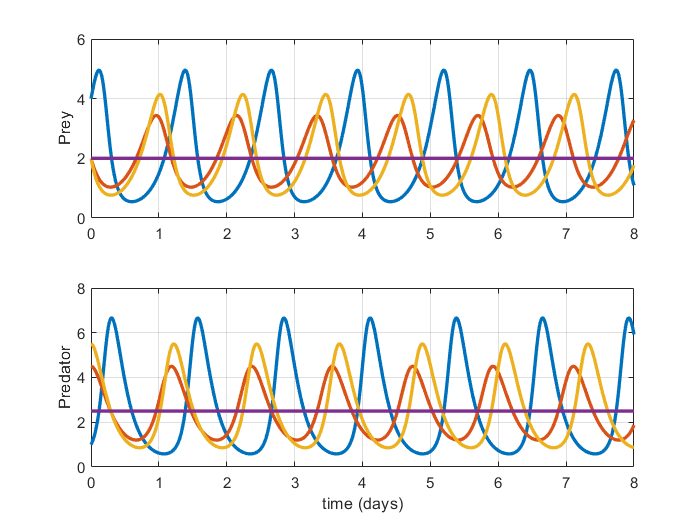


figure
subplot(211)
plot(t,prey,'LineWidth',2); grid on;
ylabel('Prey');
subplot(212)
plot(t,pred,'LineWidth',2); grid on;
ylabel('Predator');
xlabel('time (days)');

#### Definition of the ODE model/equation as a function

We now define a function that gives us the right-hand term of the differential equation. This expression will be evaluated at an instant $t$ and taking a value $x$, with the `parameters `given. As you can see, you need to pass to the function the following: 

* the value of $t$ where the function is evaluated,

* the value of $x$ where the function is evaluated,

* the parameters that allow us to define the equation.

**ODE Models**

function [dx_dt]= model_VL(t,x,params)
% Model parameters:
a= params(1);
b= params(2);
d= params(3);
g= params(4);

dx1 =  a .* x(1)          - b .* x(1) .* x(2) ;
dx2 =  d .* x(1)  .* x(2) - g .* x(2) ;

dx_dt = [dx1; dx2];

end